# Анализ принятого радио-импульса

Данный скрипт использует ядро **MATLAB**, **Signal Processing Toolbox**, а также **Communications Toolbox** для добавления к сигналу шума функцией ***awgn***

### Визуализация исходного и принятого радио-импульсов

Создадим два сигнала - исходный и принятый. В принятном импульсе, помимо задержки во времени, сразу же наблюдаем ряд искажений: присутствует аддитивный шум, размах сигнала изменяется внутри импульса, а также присутствует некий постоянный дрейф среднего значения.

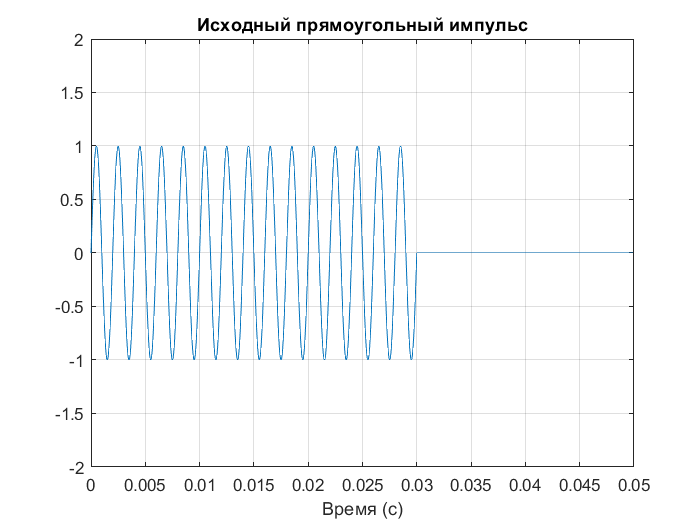

helperCreatePulseSignal

plot(timevector,originalSignal)
title('Исходный прямоугольный импульс')
xlabel('Время (с)')
ylim([-2 2]); grid;

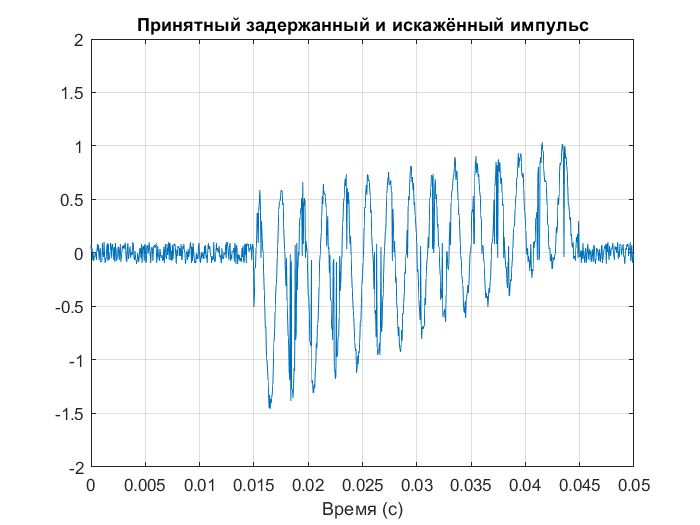

figure
plot(timevector,receivedSignal)
title('Принятный задержанный и искажённый импульс')
xlabel('Время (с)')
ylim([-2 2]); grid;

Приблизим область принятого импульса. В данных присутствуют пропуски (внесённые туда специально для демонстрации), на месте которых только значения шума. Это приводит к резким изменениям в форме принятого синусоидального сигнала.

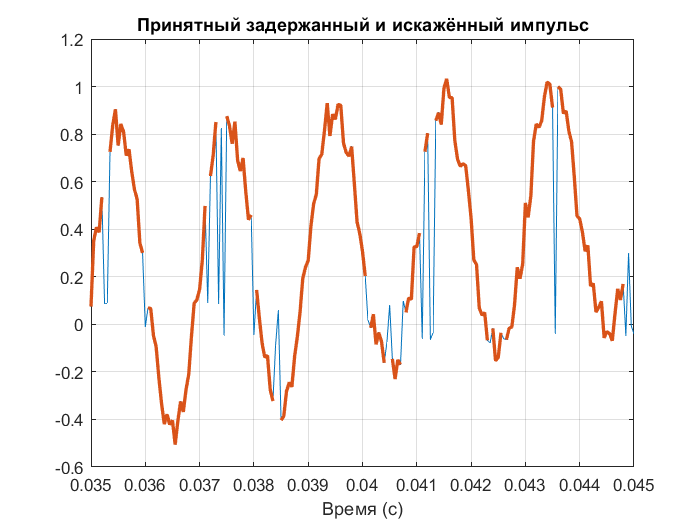

plot(timevector,receivedSignal)
hold on
plot(timeNaN,receivedSignal,'LineWidth',2)
hold off
xlim([0.035 0.045]); grid;
title('Принятный задержанный и искажённый импульс')
xlabel('Время (с)')

### Сглаживание скользящим окном

Попробуем исправить положение при помощи скользящего среднего и скользящей медианы:

winsize = 6

winsize = 6

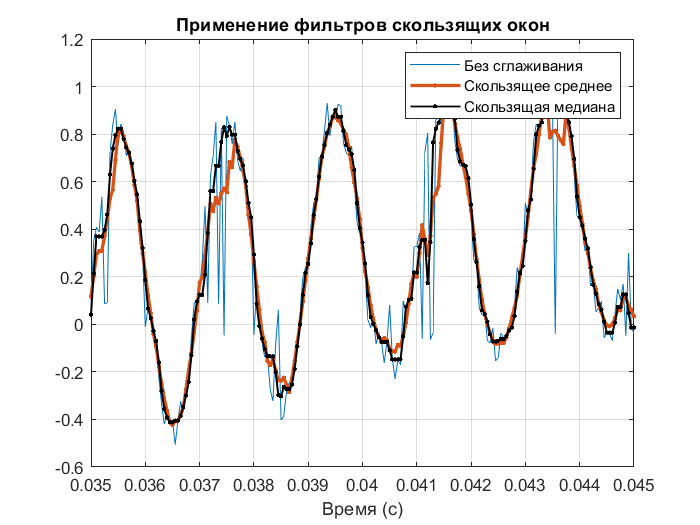

meanSignal = movmean(receivedSignal,winsize);
plot(timevector,receivedSignal)
hold on
plot(timevector,meanSignal,'.-','LineWidth',2)
medianSignal = movmedian(receivedSignal,winsize);
plot(timevector,medianSignal,'k.-','LineWidth',1)
xlim([0.035 0.045]); grid;
title('Применение фильтров скользящих окон')
xlabel('Время (с)')
legend('Без сглаживания','Скользящее среднее','Скользящая медиана')
hold off

### Изменение частоты дискретизации сигнала

Мы знаем, что в сигнале пропущены достоверные отсчёты. Если есть возможность локализовать моменты времени, в которых отсутствуют оценки значения сигнала, то можно "переложить" отсчёты на равномерную шкалу времени с произвольным шагом, используя функцию **resample**:

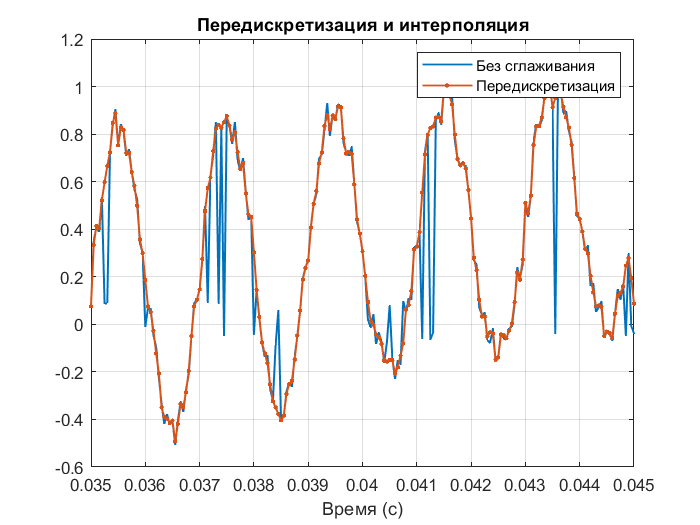

desiredFs = 20e3;
[newSignal, newtimevec] = resample(receivedSignal,timeNaN,desiredFs,'linear');

plot(timevector,receivedSignal,newtimevec,newSignal,'.-','LineWidth',1)
xlim([0.035 0.045]); grid;
title('Передискретизация и интерполяция')
xlabel('Время (с)')
legend('Без сглаживания','Передискретизация')

Теперь можно избавиться от высокочастотных шумов функцией **movmean**:

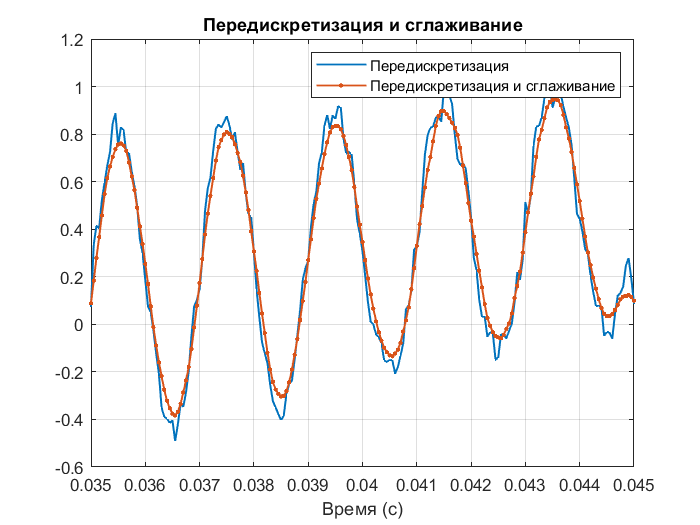

smooth = movmean(newSignal,10);
plot(newtimevec,newSignal,newtimevec,smooth,'.-','LineWidth',1)
xlim([0.035 0.045]); grid;
title('Передискретизация и сглаживание')
xlabel('Время (с)')
legend('Передискретизация','Передискретизация и сглаживание')

Однако, попытка избавиться от дрейфа постоянной составляющей приводит к неудовлетворительным результатам:

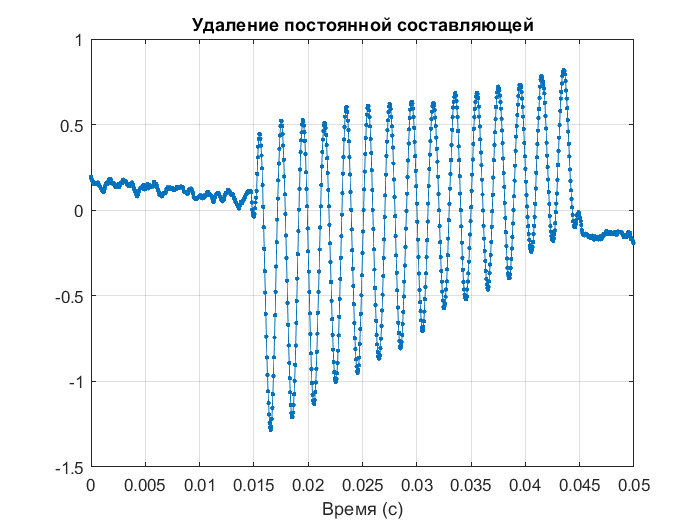

notrend = detrend(smooth);
plot(newtimevec,notrend,'.-')
grid;
title('Удаление постоянной составляющей')
xlabel('Время (с)')

### Локализация импульса во времени

Оценив взаимно-корреляционную функцию между принятным и исходным сигналами, можно оценить задержку одного относительно другого:

% [xCorr,lags] = xcorr(receivedSignal,originalSignal);
[xCorr,lags] = xcorr(smooth,originalSignal);
plot(lags,xCorr)
[~,I] = max(abs(xCorr));
maxt = lags(I)

maxt = 280

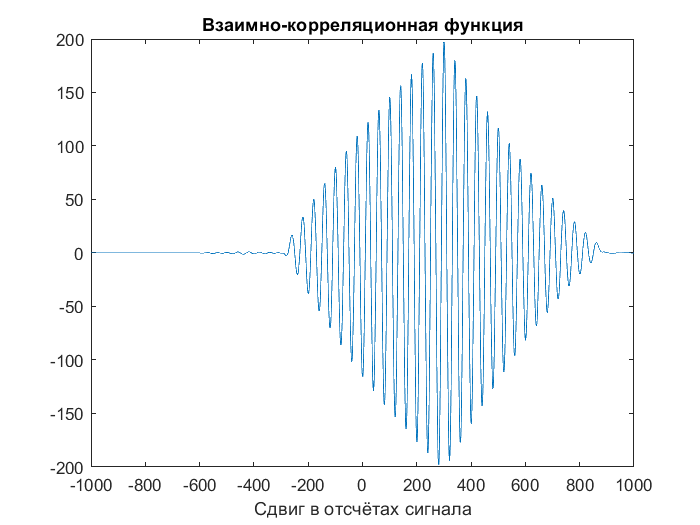

title('Взаимно-корреляционная функция')
xlabel('Сдвиг в отсчётах сигнала')

Зная длительность исходного испульса, выделим из всего принятого сигнала только отрезок с синусоидой, отобразим ег она графике:

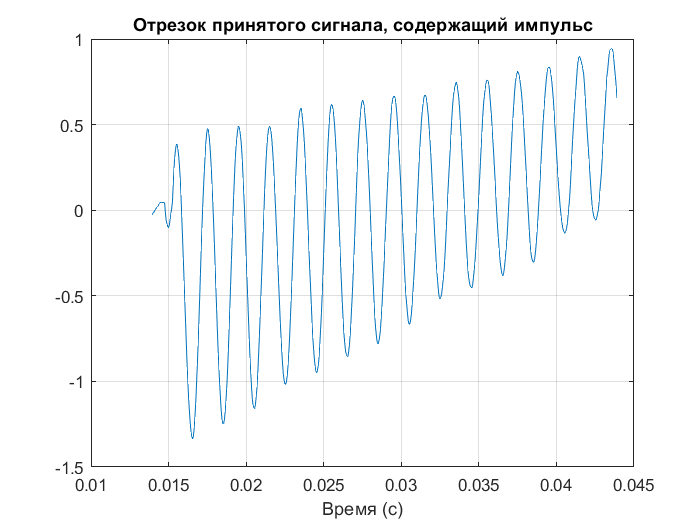

cut = smooth(maxt:maxt+599);
timecut = timevector(maxt:maxt+599);
plot(timecut,cut)
title('Отрезок принятого сигнала, содержащий импульс')
xlabel('Время (с)'); grid;

И удалим постоянную составляющую:

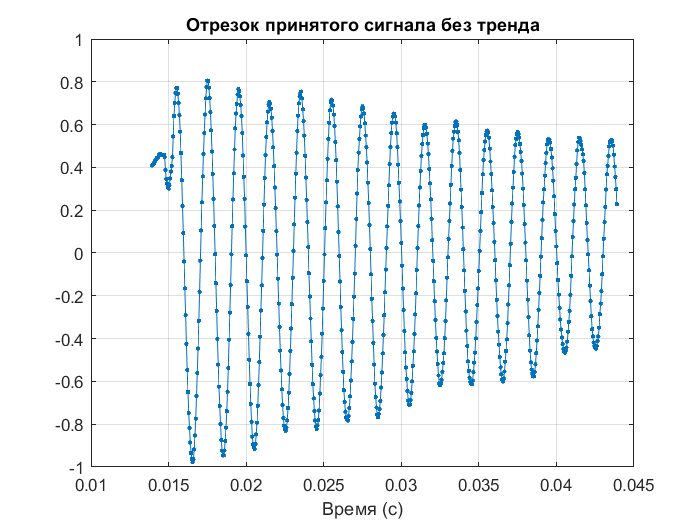

notrend = detrend(cut);
plot(timecut,notrend,'.-')
title('Отрезок принятого сигнала без тренда')
xlabel('Время (с)'); grid;

### Выделение огибающей импульса

Мы можем оценить, насколько уменьшилась амплитуда принятого импульса. Для этого выделим огибающую функцией **envelope**, и нализируем её численно.

nsamples = 300

nsamples = 300

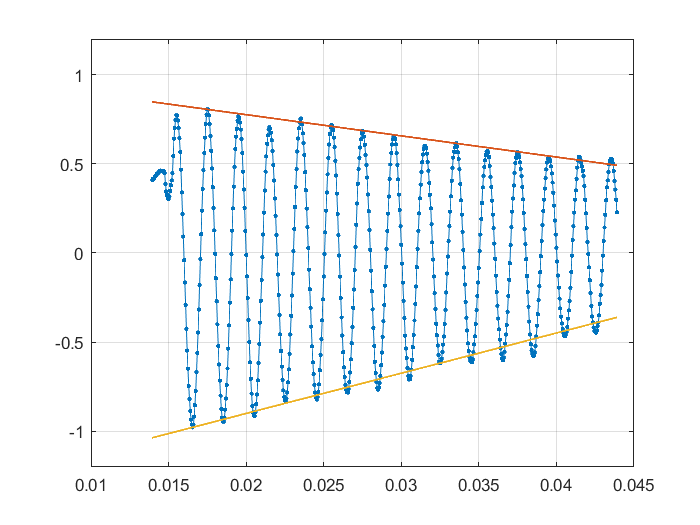

[yupper,ylower] = envelope(notrend,nsamples,'peak');
plot(timecut,notrend,'.-'); grid;
hold on
plot(timecut,yupper,'LineWidth',1)
plot(timecut,ylower,'LineWidth',1)
hold off
ylim([-1.2 1.2])

Разница верхней и нижней границ даст нам размах сигнала:

range_start = yupper(1) - ylower(1)

range_start = 1.8841

range_end = yupper(end) - ylower(end)

range_end = 0.8529

ratio = 100*(range_end/range_start)

ratio = 45.2665